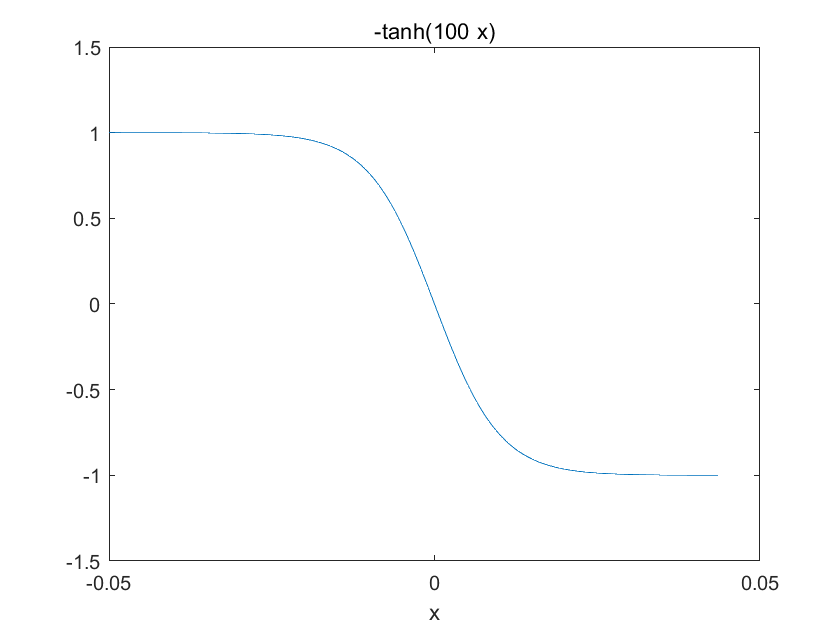

clc
clear
pic_num = 1;
for epsilon = 0.01:-0.001:0.005
    t = 1;
    syms x;
    ur = -1;
    ul = 1;
    s = (ur + ul)/2;
    w = ur + 1/2*(ul - ur)*(1-tanh((ul-ur)*(x-s*t)/(4*epsilon)));
    figure(1);
    ezplot(w);
    axis([-0.05,0.05 -1.5 1.5])
    drawnow;
    F=getframe(gcf);
    I=frame2im(F);
    [I,map]=rgb2ind(I,256);
    if pic_num == 1
        imwrite(I,map,'test.gif','gif', 'Loopcount',inf,'DelayTime',0.2);
    else
        imwrite(I,map,'test.gif','gif','WriteMode','append','DelayTime',0.2);
    end
    pic_num = pic_num + 1;
end

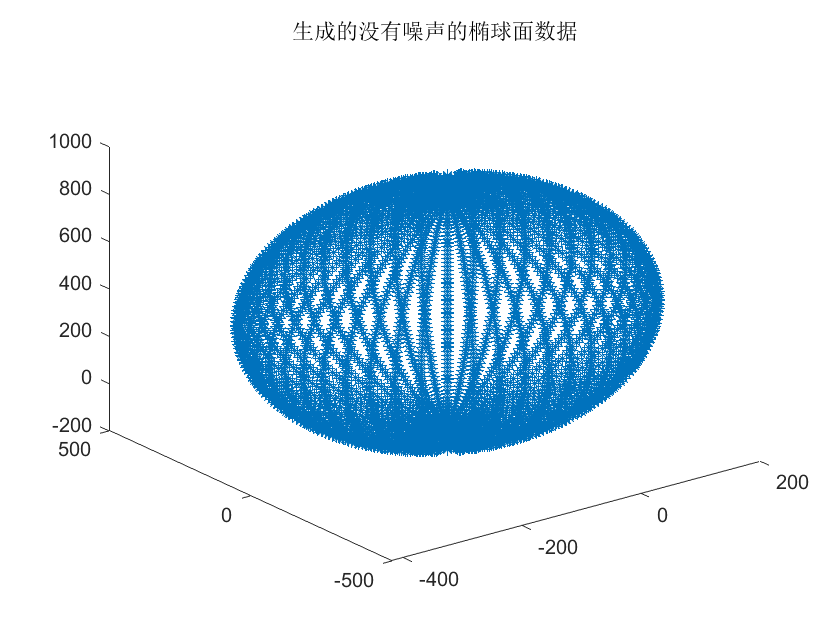

%% 生成随机椭球球面数据
% clear all;close allclc;
A = 300;     % x方向上的轴半径
B = 400;     % y方向上的轴半径
C = 500;     % z方向上的轴半径
x0 = -120;   %椭球球心x坐标
y0 = -67;    %椭球球心y坐标
z0 = 406;    %椭球球心z坐标
SNR = 30;    %信噪比

num_alfa = 100;
num_sita = 50;
alfa = (0:num_alfa-1)*1*pi/num_alfa;
sita = (0:num_sita-1)*2*pi/num_sita;
x = zeros(num_alfa,num_sita);
y = zeros(num_alfa,num_sita);
z = zeros(num_alfa,num_sita);
for i = 1:num_alfa
    for j = 1:num_sita
        x(i,j) = x0 + A*sin(alfa(i))*cos(sita(j));
        y(i,j) = y0 + B*sin(alfa(i))*sin(sita(j));
        z(i,j) = z0 + C*cos(alfa(i));
    end
end

x = reshape(x,num_alfa*num_sita,1);    %转换成一维的数组便于后续的处理
y = reshape(y,num_alfa*num_sita,1);
z = reshape(z,num_alfa*num_sita,1);
figure;
plot3(x,y,z,'*');
title('生成的没有噪声的椭球面数据');

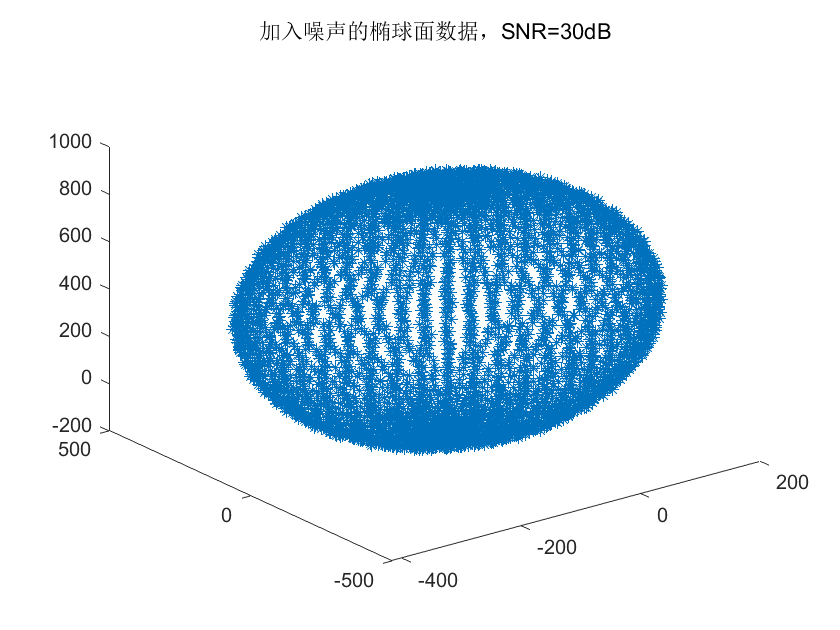


%加入均值为0的高斯分布噪声 
amp = 10^(-SNR/20)*A;
x = x + amp*rand(num_alfa*num_sita,1);
y = y + amp*B/A*rand(num_alfa*num_sita,1);
z = z + amp*C/A*rand(num_alfa*num_sita,1);
figure;
plot3(x,y,z,'*');
string = ['加入噪声的椭球面数据，SNR=',num2str(SNR),'dB'];
title(string);


%% 空间二次曲面拟合算法
num_points = length(x);
%一次项统计平均
x_avr = sum(x)/num_points;
y_avr = sum(y)/num_points;
z_avr = sum(z)/num_points;
%二次项统计平均
xx_avr = sum(x.*x)/num_points;
yy_avr = sum(y.*y)/num_points;
zz_avr = sum(z.*z)/num_points;
xy_avr = sum(x.*y)/num_points;
xz_avr = sum(x.*z)/num_points;
yz_avr = sum(y.*z)/num_points;
%三次项统计平均
xxx_avr = sum(x.*x.*x)/num_points;
xxy_avr = sum(x.*x.*y)/num_points;
xxz_avr = sum(x.*x.*z)/num_points;
xyy_avr = sum(x.*y.*y)/num_points;
xzz_avr = sum(x.*z.*z)/num_points;
yyy_avr = sum(y.*y.*y)/num_points;
yyz_avr = sum(y.*y.*z)/num_points;
yzz_avr = sum(y.*z.*z)/num_points;
zzz_avr = sum(z.*z.*z)/num_points;
%四次项统计平均
yyyy_avr = sum(y.*y.*y.*y)/num_points;
zzzz_avr = sum(z.*z.*z.*z)/num_points;
xxyy_avr = sum(x.*x.*y.*y)/num_points;
xxzz_avr = sum(x.*x.*z.*z)/num_points;
yyzz_avr = sum(y.*y.*z.*z)/num_points;

%计算求解线性方程的系数矩阵
A0 = [yyyy_avr yyzz_avr xyy_avr yyy_avr yyz_avr yy_avr;
     yyzz_avr zzzz_avr xzz_avr yzz_avr zzz_avr zz_avr;
     xyy_avr  xzz_avr  xx_avr  xy_avr  xz_avr  x_avr;
     yyy_avr  yzz_avr  xy_avr  yy_avr  yz_avr  y_avr;
     yyz_avr  zzz_avr  xz_avr  yz_avr  zz_avr  z_avr;
     yy_avr   zz_avr   x_avr   y_avr   z_avr   1;];
%计算非齐次项
b = [-xxyy_avr;
     -xxzz_avr;
     -xxx_avr;
     -xxy_avr;
     -xxz_avr;
     -xx_avr];

resoult = inv(A0)*b;
%resoult = solution_equations_n_yuan(A0,b);

x00 = -resoult(3)/2;                  %拟合出的x坐标
y00 = -resoult(4)/(2*resoult(1));     %拟合出的y坐标
z00 = -resoult(5)/(2*resoult(2));     %拟合出的z坐标

AA = sqrt(x00*x00 + resoult(1)*y00*y00 + resoult(2)*z00*z00 - resoult(6));   % 拟合出的x方向上的轴半径
BB = AA/sqrt(resoult(1));                                                    % 拟合出的y方向上的轴半径
CC = AA/sqrt(resoult(2));                                                    % 拟合出的z方向上的轴半径

fprintf('拟合结果\n');

拟合结果


fprintf('a = %f, b = %f, c = %f, d = %f, e = %f, f = %f\n',resoult);

a = 0.560958, b = 0.358793, c = 230.336545, d = 68.224275, e = -296.974584, f = -13051.822805


fprintf('x0 = %f, 相对误差%f\n',x00,abs((x00-x0)/x0));

x0 = -115.168273, 相对误差0.040264


fprintf('y0 = %f, 相对误差%f\n',y00,abs((y00-y0)/y0));

y0 = -60.810521, 相对误差0.092380


fprintf('z0 = %f, 相对误差%f\n',z00,abs((z00-z0)/z0));

z0 = 413.852608, 相对误差0.019341


fprintf('A = %f,  相对误差%f\n',AA,abs((A-AA)/A));

A = 299.736190,  相对误差0.000879


fprintf('B = %f,  相对误差%f\n',BB,abs((B-BB)/B));

B = 400.197229,  相对误差0.000493


fprintf('C = %f,  相对误差%f\n',CC,abs((C-CC)/C));

C = 500.400100,  相对误差0.000800


%需要拟合的点的坐标为(0，-174.802,990.048)，(0.472，-171.284,995.463)，(0.413，-168.639,1003.55)，(0.064，-167.862,1019.55)，
% %(0，-170.357,1035.44)，(0，-172.142,1044.78)，(0.215，-174.759,1047.84)，(0.171，-176.586,1048.13)，(0，-179.832,1043.34)，(0,181.589,1040.11)，(0，-182.76,1032.62)，(0，-184.13,1017.55)，(0.113，-183.445,1003.17)

%需要拟合的点的坐标为(0，-174.802,990.048)，(0.472，-171.284,995.463)，(0.413，-168.639,1003.55)，(0.064，-167.862,1019.55)，

%(0，-170.357,1035.44)，(0，-172.142,1044.78)，(0.215，-174.759,1047.84)，(0.171，-176.586,1048.13)，(0，-179.832,1043.34)，(0,181.589,1040.11)，(0，-182.76,1032.62)，(0，-184.13,1017.55)，(0.113，-183.445,1003.17)
my_fit_new()


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>
x1:
    0.3284

y1:
    2.9057

z1:
   1.0212e+03

a轴:
    0.7267

b轴:
  283.5757

c轴:
   29.9900



function my_fit_new()

% 日期：2011年12月29日

% 作者：半人马alpha

% 适用于你说的情况

% 你的数据拟合结果是一个旋转双曲面(a,c均为虚数，即 a^2<0,c^2<0)

% 我按拟合出的参数给你把图画了一下，是旋转双曲面的一支

% step0：生成拟合数据(例)

x = [0,0,0,0,0,0,0,0.064,0.113,0.171,0.215,0.413,0.472]';

y = [-174.802,-170.357,-172.142,-179.832,181.589,-182.760,-184.130,-167.862,-183.445,-176.586,-174.759,-168.639,-171.284]';

z = [990.048,1035.44,1044.78,1043.34,1040.11,1032.62,1017.55,1019.55,1003.17,1048.13,1047.84,1003.55,995.463]';

% step1：拟合，k表示系数，行向量

% 待拟合方程：F = z^2 = (-c^2/a^2*x^2) + (c^2/a^2*2*x1*x) + (- c^2/b^2*y^2) +

% (c^2/b^2*2*y1*y) + (2*z1*z) +

% (-c^2/a^2*x1^2 - c^2/b^2*y1^2 - z1^2 + c^2)

% x,y,z 均要先转化为列向量

% k(1) = -c^2/a^2 由k值就可求出椭圆所有参数！！！

% k(2) = c^2/a^2*2*x1

% k(3) = - c^2/b^2

% k(4) = c^2/b^2*2*y1

% k(5) = 2*z1

% k(6) = -c^2/a^2*x1^2 - c^2/b^2*y1^2 - z1^2 + c^2

xdata = [x,y,z];

ydata = z.^2; %% 先把 z 值平方，再进行拟合

k0 = ones(1,6); %% k 的运行初值，不会影响最终结果

F = @(k,xdata) k(1)*xdata(:,1).^2 + k(2)*xdata(:,1) + k(3)*xdata(:,2).^2 + k(4)*xdata(:,2) + k(5)*xdata(:,3) + k(6);

[k,resnorm]=lsqcurvefit(F,k0,xdata,ydata);

% step2：椭圆参数求解

x1 = -k(2)/k(1)/2;

y1 = -k(4)/k(3)/2;

z1 = k(5)/2;

c = sqrt(z1^2 + k(6) - k(1)*x1^2 - k(3)*y1^2);

a = c/sqrt(-k(1));

b = c/sqrt(-k(3));

disp('x1:');

disp(x1);

disp('y1:');

disp(y1);

disp('z1:');

disp(z1);

disp('a轴:');

disp(a);

disp('b轴:');

disp(b);

disp('c轴:');

disp(c);

end